# Homework 4

**Sebastian Aguilera Novoa**

## **1. Unconstrained minimization**

In this exercise we are going to implement different Newton methods to solve the following problem


$$\min_{x, y \in \mathbb{R}} \;\underbrace{\frac{1}{2}(x-1)^2+\frac{1}{2 }\left(10\left(y-x^2\right)\right)^2+\frac{1}{2} y^2}_{=: f(x, y)}$$


Plot the objective function $f(x,y)$ to get an idea of the shape is this.

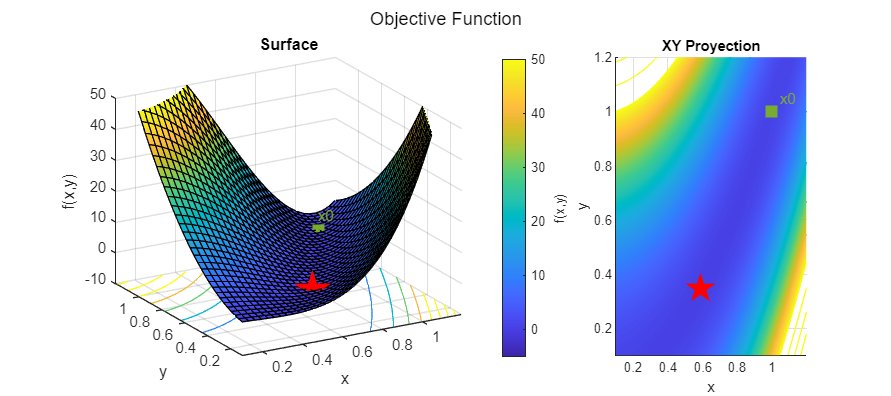

fp1 = @(x,y) 0.5*(x-1).^2 +0.5*(10*(y-x.^2)).^2 + 0.5*y.^2; x1_opt = [0.591077; 0.345913];
FinalPlot(fp1, x1_opt, [1;1], [], 1, [-30 24], "Objective Function", 1) %(f, xstar, x0, xks, flag)

The red point is the global minimum and the pink one is the starting point.

### a) Theorical Gradian and Hessian

First get in papper, the gradient and Hessian matrix of $f(x,y)$. Then, rewrite it in the form $f(x,y) = \frac{1}{2} || R(x,y)||^2_2$ where $R:\mathbb{R}^2 \to \mathbb{R}^3$ is the residual function. Determine the Hessian by the Gauss-Newton method and compare it with the exact. When do the two matrices coincide?

Jacobian


$$\nabla f (x,y)= \Big(x-1+10(y-x^2)(-2x)10,\; 10(y-x^2)10+y \Big)\\
\quad \;  = \Big(x-1-200xy+200x^3, \; -100x^2+101y \Big)
$$


The Hessian

$\nabla^2 f (x,y) = \pmatrix{
\frac{\partial^2 f}{\partial x^2} & \frac{\partial^2 f}{\partial x \partial y} \cr
\frac{\partial^2 f}{\partial y \partial x} & \frac{\partial^2 f}{\partial y^2} } = \pmatrix{
600x^2-200y+1 & -200 x \cr -200x & 101}$                    (1)

but this problem can be formulated as a least saquare problem


$$\min_{x, y \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2$$


with


$$R(x,y ) =  \Big( x-1, 10(y-x^2), y\Big)\\
\frac{1}{2} || R(x,y)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ (10(y-x^2))^2+y^2\Big]$$


that gives the same problem. Now let's calculate the Jacobian to the new vector field $R$ and then approximate the Hessian by this Jacobian


$$J = \nabla R = \pmatrix{
\frac{\partial R_1}{\partial x} & \frac{\partial R_1}{\partial y} \cr
\frac{\partial R_2}{\partial x} & \frac{\partial R_2}{\partial y} \cr
\frac{\partial R_3}{\partial x} & \frac{\partial R_3}{\partial y} } =
\pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}$$


Hessian approximantion by Newton Gauss method


$$\approx J^T J = \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}^T \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} = 
\pmatrix{
1 & -20x & 0 \cr
0 & 10 & 1  
} \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} \\
= \pmatrix{1 +400x^2 & -200x \cr
-200x & 101}$$


then (1) conincide with the last matrix if and only if 


$$1+400x^2 = 600x^2-200y+1\\
200 y =200x^2\\
y = x^2 $$


then the optimization problem is


$$\min_{x \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2\\
\quad \text{s.t.} \qquad y =  x^2$$


with


$$R(x) = R\left(x,  x^2 \right) =  \Big( x-1, 10\left( x^2-x^2\right),  x^2 \Big)\\
\frac{1}{2} || R(x)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ x^2 \Big] = \frac{1}{2} (2x^2-2x+1)$$


which is equivalent to solve


$$\min_{x \in \mathbb{R}} \;  x^2-x+\frac{1}{2} = g(x)$$


where the solution can be find by solving $g'(x) = 0 = 2x-1$, por lo tanto


$$x^* = \frac{1}{2}, \; y^*=g(x^*) = \frac{1}{4}$$


minimization problem

#### **Function, Gradients and Hessians**

f        = @(x) 0.5*(x(1)-1)^2 + 0.5*(10*(x(2)-x(1)^2))^2 + 0.5*x(2)^2;
Gradient = @(x) [200*x(1)^3+x(1)-200*x(1)*x(2)-1; -100*x(1)^2+101*x(2)]; % G(x) = H(x,y) 
Hessian  = @(x) [600*x(1)^2+1-200*x(2) -200*x(1); -200*x(1) 101];        % H(x) = H(x,y) 

R         = @(x) [x(1)-1; 10*(x(2)-x(1)^2); x(2)];
JacobianR = @(x) [1 0; -20*x(1) 10; 0 1];
HessianR  = @(x) [1+400*x(1)^2 -200*x(1);-200*x(1) 101];

xtest = [0.5911; 0.3459]; x0 = [100; 100]; 

### 0) CasADI

**One way: NLP**

import casadi.*

x   = SX.sym('x'); y = SX.sym('y');
nlp = struct('x',[x;y], 'f',0.5*(x-1)^2+0.5*100*(y-x^2)^2+0.5*y^2);
S   = nlpsol('S', 'ipopt', nlp); %disp(S)
r   = S('x0',x0,'lbg',0,'ubg',0);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

x_opt = r.x;
t_casADI_1 = S.stats.t_proc_total;
I_casADI_1 = S.stats.iter_count; %tic(t0);

**Second Way: Default**

tstart = tic();
opti  = casadi.Opti();
x_opt = opti.variable(2);

opti.minimize(f(x_opt));

opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

xopt = sol.value(x_opt);
t_casADI_2 = sol.stats.t_proc_total;
I_casADI_2 = sol.stats.iter_count; 

### **00) Matlab**

options = optimoptions('fminunc','Display','iter');%'Algorithm','quasi-newton');
t0 = tic();
[x_M, fval_M, exitflag_M, output] = fminunc(f,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3      4.90051e+09                      1.98e+08
     1           9      3.19997e+09     5.0505e-08       1.44e+08  
     2          12      7.64779e+08              1       4.95e+07  
     3          15      2.72601e+08              1        2.3e+07  
     4          18      8.21977e+07              1       9.53e+06  
     5          21      2.57264e+07              1        4.1e+06  
     6          24      7.54562e+06              1       1.72e+06  
     7          27      2.07635e+06              1        7.1e+05  
     8          30           499877              1       2.82e+05  
     9          33          97135.4              1       1.03e+05  
    10          36          15743.4              1       3.13e+04  
    11          39          5622.89              1       6.43e+03  
    12          42          5130.99              

x_M =    10.0427
  100.8531


fval_M = 5.1266e+03

exitflag_M = 1

output = struct with fields:
       iterations: 13
        funcCount: 45
         stepsize: 0.0145
     lssteplength: 1
    firstorderopt: 100.5553
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 5.078547e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


t_matlab = toc(t0);
I_matlab = output.iterations;

### b) Newton Method

Implement your own Newton method using the Hessian and complete steps. Start from the inital value $(x_0,y_0)=(1,1)$ and use it as a stop condition $|| \nabla f (x_k, y_k)||_\infty \geq 10^{-3}$. Keep a track over the iterations $(x_k,y_k)$ and add it to the contour plot.


$$f(x_k+t) \approx f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2$$


has a minimum 


$$\frac{d}{dt} f(x_k+t) = \frac{d}{dt} \left(f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2\right) = 0 \\
\nabla f (x_k) +  t = 0\\
t = - \nabla^2 f(x_k) ^{-1} \nabla f (x_k) =  - \nabla^2 f_k ^{-1} \nabla f_k$$



$$x_{k+1} = x_k  -  \nabla^2f_k^{-1} \nabla f_k$$


Newton = @(xk) -Hessian(xk)\Gradient(xk); 
[xk_Newton, c_Newton, time_Newton] = Iteration(x0, Newton, Gradient)

xk_Newton = 1.0e+03 *

    0.1000    0.0990    0.0661    0.0637    0.0434    0.0417    0.0286    0.0274    0.0188    0.0180    0.0123    0.0118    0.0081    0.0078    0.0053    0.0051    0.0035    0.0033    0.0023    0.0022    0.0015    0.0014    0.0010    0.0009    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006
    0.1000    9.7068    3.2568    4.0166    1.4598    1.7175    0.6369    0.7405    0.2761    0.3200    0.1195    0.1383    0.0516    0.0597    0.0222    0.0257    0.0095    0.0110    0.0040    0.0047    0.0017    0.0020    0.0008    0.0009    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003


c_Newton = 30

time_Newton = 0.0049

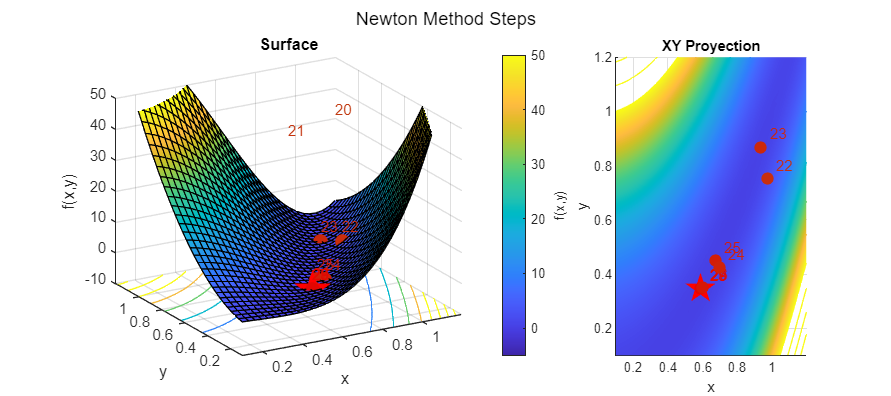

FinalPlot(fp1, x1_opt, x0, xk_Newton(:,2:end-1), 1, [-30 24], "Newton Method Steps", 1)

### c) Gauss- Newton Method

Update by adding a Newton type method that uses the Hessian of the Gauss-Newton method instead. Add the resultant iterations$(x_k,y_k)$  to the plot.

%GaussNewtonApprox  = @(xk) -(Gradient(xk)'*Gradient(xk))\ (Gradient(xk));%'*f(xk));
%[xk_GN, c_GN] = Iteration(x0, GaussNewtonR, Gradient)
GaussNewton = @(xk) -HessianR(xk)\Gradient(xk); 
[xk_GN, c_GN, time_GN] = Iteration(x0, GaussNewton, Gradient)

xk_GN =   100.0000   49.9988   24.9970   12.4938    6.2384    3.1056    1.5387    0.7916    0.5693    0.5979    0.5891    0.5916    0.5909    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911
  100.0000   -0.2450   -0.2400   -0.2299   -0.2096   -0.1688   -0.0867    0.0677    0.2720    0.3531    0.3436    0.3466    0.3457    0.3460    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459


c_GN = 21

time_GN = 0.0027

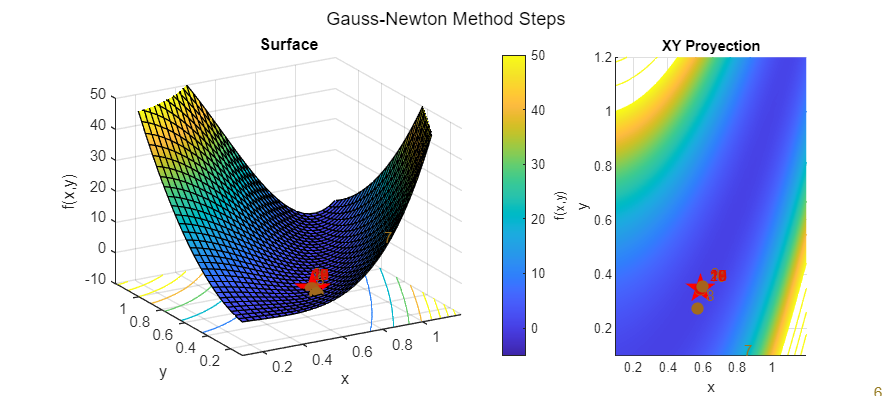

FinalPlot(fp1, x1_opt, x0, xk_GN(:,2:end-1), 1, [-30 24], "Gauss-Newton Method Steps", 1);

### d) Add Regularization

Check how the steepest descent method works in this example. Now the Hessian approximation is $\alpha I$, where $\alpha$ is a positive scalar and $I$ is the identity matrix of appropiate size. What values does the algorithm converge for?

- 
$$\alpha=1$$


HessianApprox  = @(xk) -(Hessian(xk)+0.001*eye(size(xk,1)))\Gradient(xk);
%HessianApproxR = @(xk) -(HessianR(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
[xk_reg0, c_reg0, time_reg0] = Iteration(x0, HessianApprox, Gradient)

xk_reg0 = 1.0e+03 *

    0.1000    0.0990    0.0662    0.0638    0.0435    0.0417    0.0286    0.0274    0.0188    0.0180    0.0124    0.0119    0.0081    0.0078    0.0053    0.0051    0.0035    0.0034    0.0023    0.0022    0.0015    0.0014    0.0010    0.0009    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006
    0.1000    9.7065    3.2632    4.0196    1.4634    1.7200    0.6388    0.7421    0.2772    0.3209    0.1200    0.1388    0.0518    0.0600    0.0223    0.0259    0.0095    0.0111    0.0040    0.0047    0.0017    0.0020    0.0008    0.0009    0.0004    0.0005    0.0004    0.0003    0.0003    0.0003    0.0003


c_reg0 = 30

time_reg0 = 0.0032

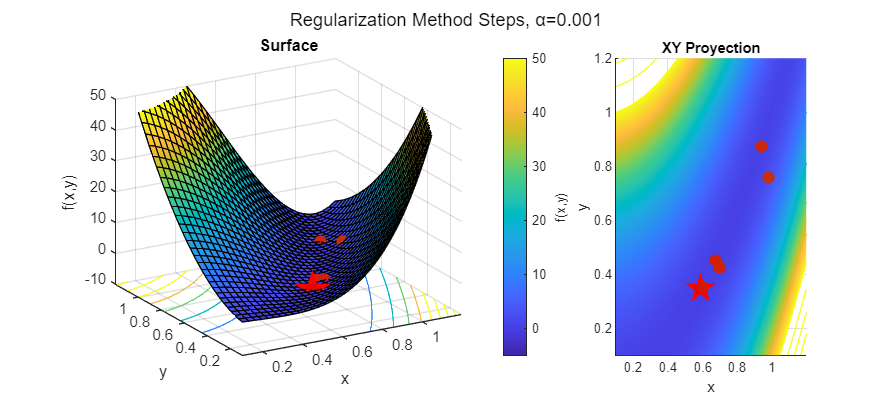

FinalPlot(fp1, x1_opt, x0, xk_reg0(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=0.001", 1)

- 
$$\alpha=1$$


alpha = 1; HessianApprox  = @(xk) -(Hessian(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
%HessianApproxR = @(xk) -(HessianR(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
[xk_reg1, c_reg1, time_reg1] = Iteration(x0, HessianApprox, Gradient)

xk_reg1 = 1.0e+03 *

    0.1000    0.0981    0.0815    0.0717    0.0606    0.0527    0.0449    0.0389    0.0333    0.0287    0.0246    0.0212    0.0182    0.0156    0.0134    0.0116    0.0099    0.0085    0.0073    0.0063    0.0054    0.0046    0.0040    0.0034    0.0029    0.0025    0.0022    0.0019    0.0016    0.0014    0.0012    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.1000    9.4332    6.3347    5.0132    3.5314    2.7009    1.9476    1.4646    1.0687    0.7968    0.5850    0.4342    0.3198    0.2368    0.1746    0.1291    0.0953    0.0704    0.0520    0.0384    0.0283    0.0209    0.0154    0.0113    0.0083    0.0061    0.0045    0.0033    0.0024    0.0018    0.0013    0.0010    0.0008    0.0006    0.0005    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.00

c_reg1 = 55

time_reg1 = 0.0027

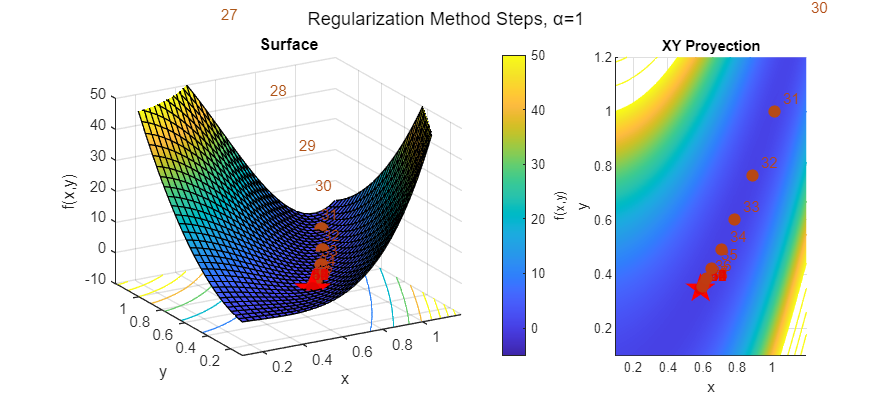

FinalPlot(fp1, x1_opt, x0, xk_reg1(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=1", 1)

%[xk_reg_R, c_reg_R, time_reg_R] = Iteration(x0, HessianApproxR, Gradient)
%xk_reg_R(:,end)'
%FinalPlot(fp1, x1_opt, x0, xk_reg_R(:,2:end-1), 1, [-30 24], "Regularization Method Steps with HessianR", 1)

- 
$$\alpha=100$$


HessianApprox  = @(xk) -(Hessian(xk)+100*eye(size(xk,1)))\Gradient(xk);
[xk_reg2, c_reg2, time_reg2] = Iteration(x0, HessianApprox, Gradient)

xk_reg2 = 1.0e+03 *

    0.1000    0.0751    0.0616    0.0564    0.0554    0.0551    0.0548    0.0546    0.0543    0.0540    0.0538    0.0535    0.0532    0.0530    0.0527    0.0524    0.0522    0.0519    0.0517    0.0514    0.0511    0.0509    0.0506    0.0504    0.0501    0.0499    0.0496    0.0494    0.0492    0.0489    0.0487    0.0484    0.0482    0.0479    0.0477    0.0475    0.0472    0.0470    0.0468    0.0465    0.0463    0.0461    0.0458    0.0456    0.0454    0.0452    0.0449    0.0447    0.0445    0.0443
    0.1000    2.5435    3.0658    3.0967    3.0676    3.0373    3.0072    2.9774    2.9479    2.9187    2.8898    2.8612    2.8329    2.8048    2.7771    2.7496    2.7223    2.6954    2.6687    2.6423    2.6161    2.5902    2.5646    2.5392    2.5140    2.4891    2.4645    2.4401    2.4159    2.3920    2.3683    2.3449    2.3216    2.2987    2.2759    2.2534    2.2310    2.2090    2.1871    2.1654    2.1440    2.1228    2.1017    2.0809    2.0603    2.0399    2.0197    1.99

c_reg2 = 2248

time_reg2 = 0.0295

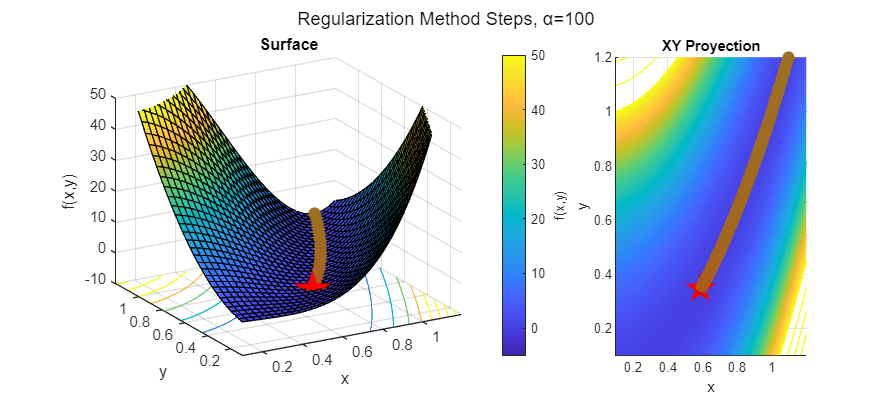

FinalPlot(fp1, x1_opt, x0, xk_reg2(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=100", 0)

- 
$$\alpha=200$$


HessianApprox  = @(xk) -(Hessian(xk)+200*eye(size(xk,1)))\Gradient(xk);
[xk_reg3, c_reg3, time_reg3] = Iteration(x0, HessianApprox, Gradient)

xk_reg3 = 1.0e+03 *

    0.1000    0.0716    0.0550    0.0470    0.0447    0.0444    0.0442    0.0441    0.0440    0.0439    0.0438    0.0437    0.0436    0.0435    0.0434    0.0433    0.0432    0.0430    0.0429    0.0428    0.0427    0.0426    0.0425    0.0424    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0416    0.0415    0.0414    0.0413    0.0412    0.0411    0.0410    0.0408    0.0407    0.0406    0.0405    0.0404    0.0403    0.0402    0.0401    0.0400    0.0399    0.0398    0.0397
    0.1000    1.4998    1.9100    1.9813    1.9770    1.9672    1.9574    1.9477    1.9380    1.9284    1.9188    1.9092    1.8997    1.8903    1.8809    1.8715    1.8622    1.8529    1.8437    1.8345    1.8254    1.8163    1.8073    1.7983    1.7894    1.7805    1.7716    1.7628    1.7540    1.7453    1.7366    1.7280    1.7194    1.7108    1.7023    1.6938    1.6854    1.6770    1.6687    1.6604    1.6521    1.6439    1.6357    1.6276    1.6195    1.6114    1.6034    1.59

c_reg3 = 4390

time_reg3 = 0.0575

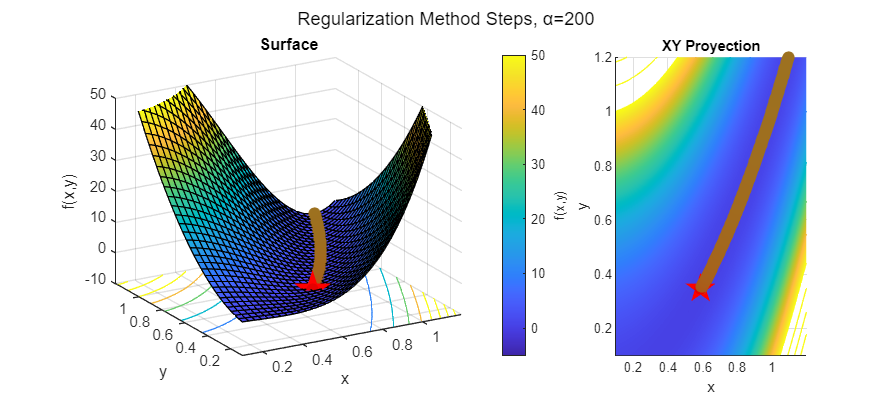

FinalPlot(fp1, x1_opt, x0, xk_reg3(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=200", 0)

- 
$$\alpha=500$$


HessianApprox  = @(xk) -(Hessian(xk)+500*eye(size(xk,1)))\Gradient(xk);
[xk_reg4, c_reg4, time_reg4] = Iteration(x0, HessianApprox, Gradient)

xk_reg4 = 1.0e+03 *

    0.1000    0.0689    0.0495    0.0384    0.0332    0.0319    0.0318    0.0318    0.0318    0.0317    0.0317    0.0317    0.0316    0.0316    0.0316    0.0315    0.0315    0.0315    0.0314    0.0314    0.0314    0.0314    0.0313    0.0313    0.0313    0.0312    0.0312    0.0312    0.0311    0.0311    0.0311    0.0310    0.0310    0.0310    0.0309    0.0309    0.0309    0.0309    0.0308    0.0308    0.0308    0.0307    0.0307    0.0307    0.0306    0.0306    0.0306    0.0305    0.0305    0.0305
    0.1000    0.7136    0.9393    1.0057    1.0162    1.0149    1.0129    1.0108    1.0088    1.0068    1.0048    1.0028    1.0008    0.9988    0.9968    0.9948    0.9928    0.9908    0.9889    0.9869    0.9849    0.9830    0.9810    0.9790    0.9771    0.9751    0.9732    0.9712    0.9693    0.9674    0.9654    0.9635    0.9616    0.9597    0.9577    0.9558    0.9539    0.9520    0.9501    0.9482    0.9463    0.9444    0.9426    0.9407    0.9388    0.9369    0.9351    0.93

c_reg4 = 10617

time_reg4 = 0.1717

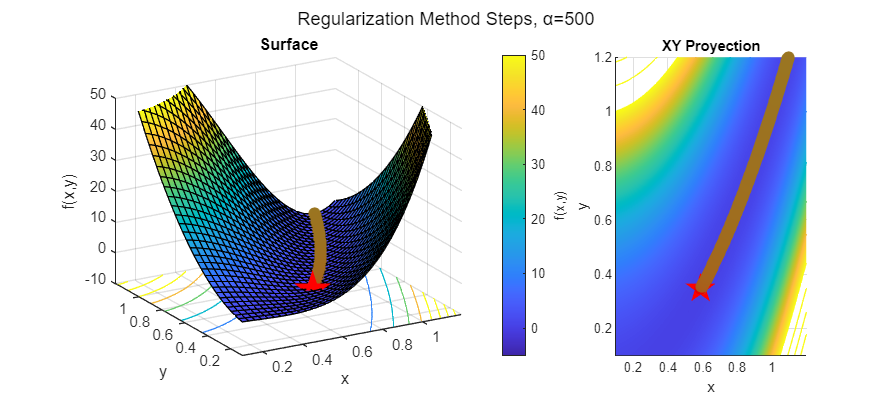

FinalPlot(fp1, x1_opt, x0, xk_reg4(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=500", 0)

### e) Methods Performance

Compare the performance of the implemented methods. Consider the iteration path $(x_k,y_k)$, the number of iterations and the execution time. To measure the time, you can use the command `tic `and `toc `from Matlab.

Method  = ["Newton"; "Gauss-Newton"; "Regularization, α=1e-3";"Regularization, α=1"; "Regularization, α=100";
           "Regularization, α=200"; "Regularization, α=500"; "CasADI 1"; "CasADI NLP"; "Matlab"];
Time    = [time_Newton; time_GN; time_reg0; time_reg1; time_reg2; time_reg3; time_reg4; t_casADI_1; t_casADI_2; t_matlab]; 
No_Iter = [c_Newton; c_GN; c_reg0; c_reg1; c_reg2; c_reg3; c_reg4; I_casADI_1; I_casADI_2; I_matlab];
tabla   = table(Method, Time, No_Iter)

tabla = 10×3 table
             Method               Time       No_Iter
    ________________________    _________    _______

    "Newton"                     0.004858        30 
    "Gauss-Newton"               0.002701        21 
    "Regularization, α=1e-3"    0.0031751        30 
    "Regularization, α=1"       0.0026988        55 
    "Regularization, α=100"      0.029485      2248 
    "Regularization, α=200"      0.057508      4390 
    "Regularization, α=500"       0.17174     10617 
    "CasADI 1"                      0.533        34 
    "CasADI 2"                      0.088         8 
    "Matlab"                     0.041975        13 


When the start point is $(1,1)^T$ and the tolerance is $10^{-8}$, difference between solutions $|x_{k+1}-x_{k}|<\text{tol}$.

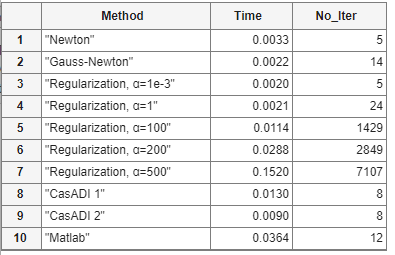

## 2. Methods Implementation

Armijo Rule: $$f\left(x_k+\alpha p_k\right) \leq f\left(x_k\right)+c_1 \alpha \nabla f_k^T p_k$,$

Iteration formula: $x_{k+1} = x_k+ \alpha_k p_k$

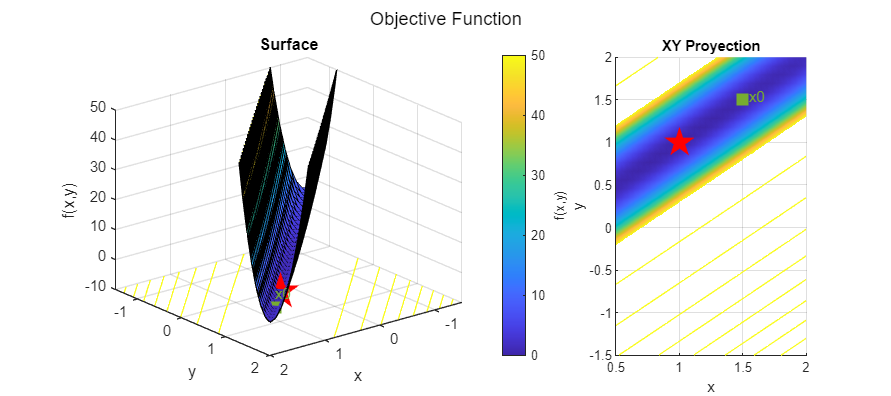

fp2 = @(x,y) 100*(y-x)^2 + (1-x)^2; x2_opt = [1; 1];
FinalPlot(fp2, x2_opt, [1.5;1.5], [], 0, [-218.8 25.2], "Objective Function", 1); %(f, xstar, x0, xks, flag)

### 0) Comparison

Using each of the previous methods solve


$$\underset{x_1,x_2\in \mathbb{R}}{min} \quad \underbrace{100 (x_2-x_1)^2 +(1-x_1)^2}_{=f(x_1,x_2)}$$



$$f(x_1, x_2) = || R(x_1, x_2)||\\
R(x_1, x_2) = \big(10(x_2-x_1), 1-x_1\big)$$


Take as initial value $(1.5, 1.5)^T$, the optimum value is $(1,1)$. The algorithm output have to show a table with the following information


$$k \qquad x_k \qquad  f(x_k) \qquad \nabla f(x_k)  \qquad  p_k  \qquad  t^*$$


Compare the performance of the methods.

#### **Gradient and Hessian **


$$\nabla f= \big(-(2)100(x_2-x_1) -2 (1-x_1), (2)100(x_2-x_1)\big)\\
\nabla f= \big(200(x_1-x_2) -2 +2x_1, \;200(x_2-x_1)\big)\\
\nabla^2 f (x,y) = \pmatrix{
200+2 & -200 \cr -200  & 200} = \pmatrix{
202 & -200 \cr -200  & 200} $$


#### Rules

global c1 c2 alpha0 rho
global Armijo Wolfe StrongWolfe % Goldstein

f        = @(x) 100*(x(2)-x(1))^2 + (1-x(1))^2;
Gradient = @(x) [200*(x(1)-x(2))-2+2*x(1); 200*(x(2)-x(1))]; % G(x) = H(x,y) 
Hessian  = @(x) [202 -200; -200 200];        % H(x) = H(x,y) 

Armijo      = @(xk, f, Gradient, pk, alphak) f(xk+alphak*pk) <= f(xk)+c1*alphak*Gradient(xk)'*pk;
Wolfe       = @(xk, f, Gradient, pk, alphak) (Gradient(xk+alphak*pk)'*pk >= c2 * Gradient(xk)'* pk)*Armijo(xk, f, Gradient, pk, alphak);
StrongWolfe = @(xk, f, Gradient, pk, alphak) (norm(Gradient(xk+alphak*pk)'*pk,2) >= c2 * norm(Gradient(xk)'* pk,2))*Armijo(xk, f, Gradient, pk, alphak);
%Goldstein   = @(xk, f, Gradient, pk, alphak) f(xk)+(1-c)*alphak*Gradient(xk)'*pk <= f(xk)+c*alphak*Gradient(xk)'*pk;   

c1 = 1e-4; c2 = 0.9; alpha0 = 1; rho=1/2; %c1 = 1e-4
x0 = [100*1.5; 100*1.5];

### 00) Solution by Matlab

This problem can be write as a quadratic problem as follows


$$R = \pmatrix{-10 & 10 \cr -1 & 0} \pmatrix{x_1 \cr x_2}+\pmatrix{0 \cr 1} = Ax+b\\
R^T = x^TA^T +b^T\\
f = ||R|| = R^TR = (x^TA^T +b^T) (Ax+b)= x^TA^TAx+2b^TAx+b^Tb\\
f = \frac{1}{2} x^THx+g^Tx\\
H = 2 A^TA, \quad g^T = 2b^TA, \quad b^Tb=1$$


then the problem can be formulated as, omiting the constant part


$$\underset{x\in \mathbb{R}^2}{min} \quad  \frac{1}{2} x^THx+g^Tx$$


where $H = 2 A^TA$ and $g^T = 2b^TA$.

options = optimoptions('quadprog','Display','iter');
A = [-10 10; -1 0]; b = [0; 1];
H = 2*(A')*A;  g = 2*A'*b;
tStart = tic();
[x,fval,exitflag,output,lambda] = quadprog(H,g,[],[],[],[],[],[],[150; 30],options)

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -1.000000e+00   0.000000e+00   9.999999e-08     0.000000e+00  
    1   -1.000000e+00   0.000000e+00   5.002221e-11     0.000000e+00  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

x =     1.0000
    1.0000


fval = -1.0000

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.476347e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.0022e-11
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [2×1 double]
      upper: [2×1 double]


tstar_Matlab = toc(tStart);

### 000) CasADI

tstart = tic();
opti  = casadi.Opti();
x_opt = opti.variable(2);

opti.minimize(0.5*x_opt'*H*x_opt+g'*x_opt);

opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

xopt = sol.value(x_opt);
tstart_casADI = toc(tstart);

### a) Steepest Descent

Such that employs the backward globalization technique with Armijo rule.


$$p_k = \nabla f_k$$


pk_func_SD = @(xk) -Gradient(xk);
[ks_SD, xks_SD, fks_SD, grad_SD, pks_SD, tstar_SD, I_SD] = MethodImpl(pk_func_SD, x0, Gradient, f, Armijo);
Tabla(xks_SD, ks_SD, grad_SD, pks_SD, fks_SD)

ans = 1916×8 table
    k       x         y         f      Grad_x     Grad_y      pk_x       pk_y  
    __    ______    ______    _____    _______    _______    _______    _______

     1       150       150    22201        298          0       -298          0
     2    147.67       150    22055    -172.28     465.62     172.28    -465.62
     3    148.01    149.09    21729     77.574     216.44    -77.574    -216.44
     4     146.8    145.71    21375     509.12    -217.52    -509.12     217.52
     5     145.8    146.13    20979     223.28      66.32    -223.28     -66.32
     6    142.31     145.1    20745     -274.2     556.83      274.2    -556.83
     7    142.85    144.01    20256      51.49     232.21     -51.49

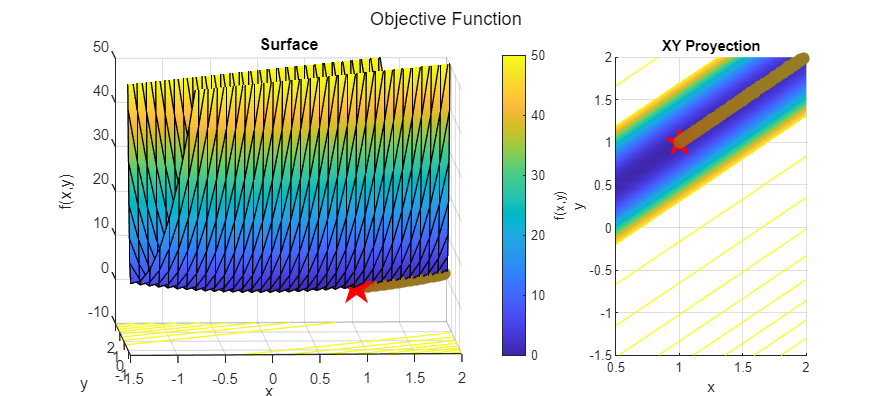

FinalPlot(fp2, x2_opt, x0, xks_SD(:,2:end-1), 0, [-2.62,6.87], "Objective Function", 0)

### b) Newton 

Such that employs the backward globalization technique with Armijo rule.


$$p_k^N = -(\nabla^2 f_k)^{-1}\nabla f_k$$


pk_func_Newton = @(xk) -Hessian(xk)\Gradient(xk);
[ks_N, xks_N, fks_N, grad_N, pks_N, tstar_N, I_N] = MethodImpl(pk_func_Newton, x0, Gradient, f, Armijo);
Tabla(xks_N, ks_N, grad_N, pks_N, fks_N)

ans = 3×8 table
    k     x      y         f           Grad_x      Grad_y       pk_x           pk_y    
    _    ___    ___    __________    __________    ______    ___________    ___________

    1    150    150         22201           298      0              -149           -149
    2      1      1    3.1052e-24    3.5243e-12      0       -1.7621e-12    -1.7621e-12
    3      1      1             0             0      0                 0              0


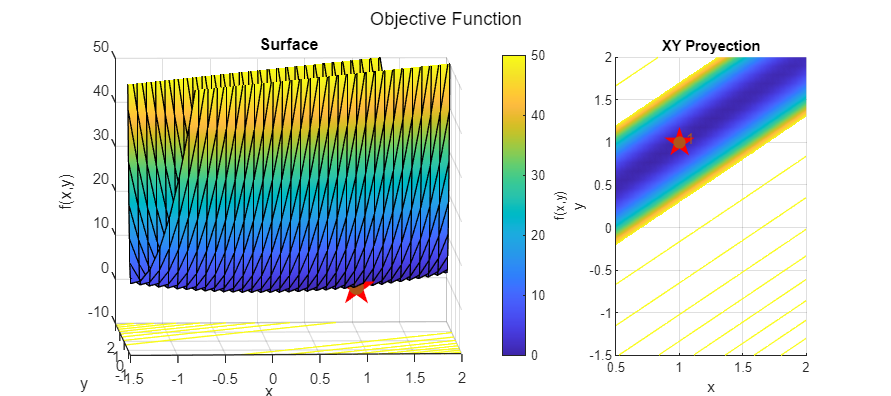

FinalPlot(fp2, x2_opt, x0, xks_N(:,2:end-1), 0, [-2.62,6.87], "Objective Function", 1)

### c) Quasi-Newton BFGS

Such that employs the backward globalization technique with Armijo rule


$$s_k = x_{k+1}-x_k, \qquad y_k = \nabla f_{k+1} - \nabla f_k, \qquad B_{k+1} s_k = y_k$$



$$B_{k+1} = B_k - \frac{B_k s_k s_k^T B_k}{s_k^T B_k s_k} + \frac{y_k y_k^T}{y_k^T y_k}$$



$$p_k = -B_k^{-1}\nabla f_k$$


[ks_BFGS, xks_BFGS, fks_BFGS, grad_BFGS, pks_BFGS, tstar_BFGS, I_BFGS] = MethodBFGS(x0, Gradient, f, Armijo);
Tabla(xks_BFGS, ks_BFGS, grad_BFGS, pks_BFGS, fks_BFGS)

ans = 35×8 table
    k        x          y           f          Grad_x     Grad_y       pk_x        pk_y  
    __    _______    _______    __________    ________    _______    ________    ________

     1        150        150         22201         298          0        -298           0
     2     147.67        150         22055     -172.28     465.62      172.28     -465.62
     3     148.01     149.09         21729      77.574     216.44     -443.96     -293.25
     4     134.13     139.93         21080     -892.15     1158.4      38.646     -2138.5
     5     134.21     135.75         17982     -41.531     307.95     -6276.5     -5557.6
     6      36.14     48.912         17548     -2484.2     2554.5     -1950.4   

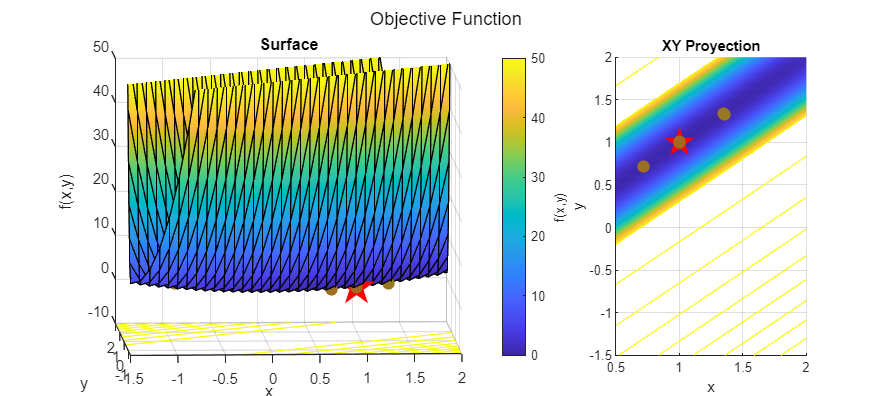

FinalPlot(fp2, x2_opt, x0, xks_BFGS(:,2:end-1), 0, [-2.62,6.87], "Objective Function",0)

### d) Newton Dogleg Trust Region

Such that employs the backward globalization technique with the Dogleg trust region. 


$$\underset{x\in \mathbb{R}^2}{min} \quad  f^T +g^Tx+ \frac{1}{2} x^THx$$


First, let's verify that the matrix $H$ is positive defined by checking its eigenvalues

eig(H)'

ans =     0.9975  401.0025


as you can see both are nonzero positive numbers, then the matrix $H$ is positive defined.

[xks_NDTR,time_NDTR, Ies, fks_NDTR, grad_NDTR, pks_NDTR] = NewtonTrustRegion(10000, x0, f, Gradient, Hessian);
clf;

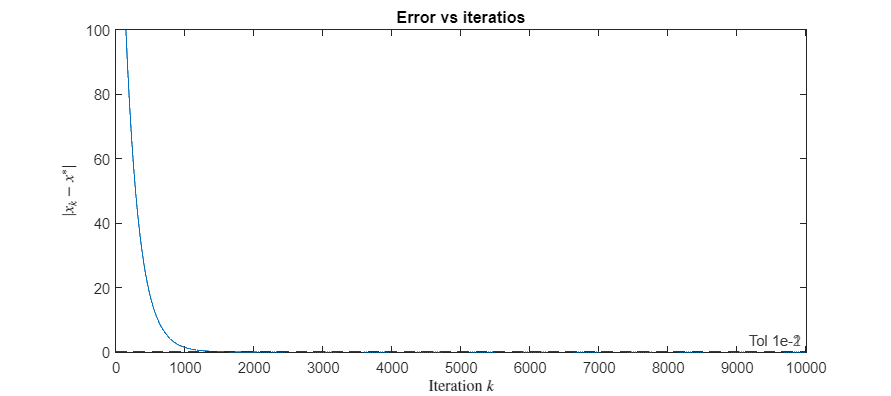

figure('Position', [10 10 900 400])
plot(1:10000+1, Ies)
yline(1e-1, '--', Label='Tol 1e-1'); yline(1e-2, '--', Label='Tol 1e-2');
ylabel("$|x_{k}-x^*|$",Interpreter="latex")
xlabel("Iteration $k$",Interpreter="latex")
xlim([0 10010]); ylim([0 100]) 
title("Error vs iteratios")

tol1_ind = find(Ies < 1e-1); tol1_ind = tol1_ind(1);
tol2_ind = find(Ies < 1e-3); tol2_ind = tol2_ind(1);
tol3_ind = find(Ies < 1e-8); tol3_ind = tol3_ind(1);
disp(['Required iteratios to get a tolerance of 1e-1 ' num2str(tol1_ind) newline...
      'Required iteratios to get a tolerance of 1e-3 ' num2str(tol2_ind) newline ...
      'Required iteratios to get a tolerance of 1e-8 ' num2str(tol3_ind)])

Required iteratios to get a tolerance of 1e-1 1540
Required iteratios to get a tolerance of 1e-3 2465
Required iteratios to get a tolerance of 1e-8 4780


[xks_NDTR,time_NDTR, Ies, ks_NDTR, fks_NDTR, grad_NDTR, pks_NDTR] = NewtonTrustRegion(tol3_ind, x0, f, Gradient, Hessian);
T_NDTR = Tabla(xks_NDTR, ks_NDTR, grad_NDTR, pks_NDTR, fks_NDTR)

T_NDTR = 4781×8 table
    k       x         y         f      Grad_x    Grad_y      pk_x        pk_y  
    __    ______    ______    _____    ______    ______    ________    ________

     1       150       150    22201       298         0        -0.5           0
     2     149.5       150    22077       197       100        -0.5           0
     3    148.61    149.55    21876    107.41    187.81    -0.89169    -0.45264
     4    148.11    148.68    21674    180.74    113.48    -0.49643    -0.86808
     5    147.26    148.15    21471    116.02    176.51     -0.8469    -0.53175
     6    146.72    147.31    21269     172.2    119.23    -0.54925    -0.83566
     7    145.89    146.74    21066    119.98    169.81    -0.822

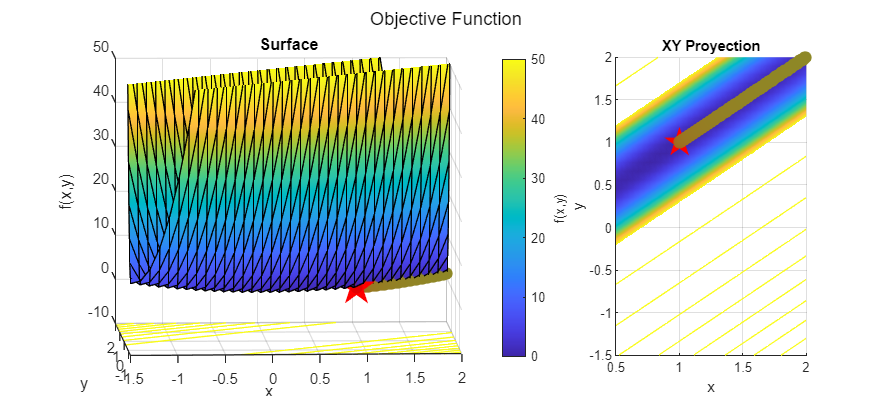

FinalPlot(fp2, x2_opt, x0, xks_NDTR(:,2:end-1), 0, [-2.62,6.87], "Objective Function",0)

Method  = ["Steepest Descent"; "Newton"; "BFGS"; "Newton Trust Region"; "Matlab-quadprog"; "CasADI"];% "Newton Trust Dogleg"];

Time    = [tstar_SD; tstar_N; tstar_BFGS; time_NDTR; tstar_Matlab; tstart_casADI];
No_Tter = [I_SD; I_N; I_BFGS; tol3_ind; output.iterations; sol.stats.iter_count];
table(Method, Time, No_Tter)

ans = 6×3 table
           Method              Time       No_Tter
    _____________________    _________    _______

    "Steepest Descent"         0.09581     1915  
    "Newton"                 0.0027196        2  
    "BFGS"                   0.0063944       34  
    "Newton Trust Region"      0.11613     4780  
    "Matlab-quadprog"         0.034601        1  
    "CasADI"                    3.7574        1  


When the start point is $(1.5,1.5)^T$ and the tolerance is $10^{-8}$, difference between solutions $|x_{k+1}-x_{k}|<\text{tol}$.

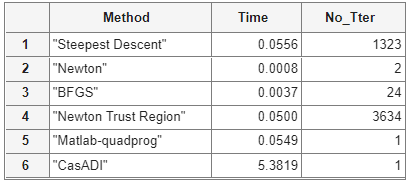

## Auxiliar Functions

### Methods Implementation

function alphak = Backtracking(xk, f, Gradient, pk, Rule)
    global alpha0 rho
    alpha = alpha0;  %c = 0;
    while not(Rule(xk, f, Gradient, pk, alpha)) %&& c<100
        alpha = rho*alpha; %c = c+1;
    end
    alphak = alpha; %display(c)
end

function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodBFGS(x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    Bk        = eye(2);
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [-Bk\Gradient(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        
        xks       = [xks xks(:,end)+alphak*pks(:,end)];
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks -Bk\Gradient(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        sk = xks(:,end) - xks(:,end-1);
        yk = Gradient(xks(:,end)) - Gradient(xks(:,end-1));
        Bk = Bk - (Bk*(sk*sk')*Bk')/(sk'*Bk*sk)+(yk*yk')/(yk'*yk);

        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i-1;
    %display(tstar);
end


function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodImpl(pk_func, x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [pk_func(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        xks    = [xks xks(:,end)+alphak*pks(:,end)];
        
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks pk_func(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i-1;
    %display(tstar);
end

function [xk,c,time] = Iteration(x0, func, Gradient)
    tStart = tic;
    xk = [x0]; tol = 1e-8; %MaxIter = 500; c = 0; 
    while norm(Gradient(xk(:,end)), "inf")  >= tol % && (c < MaxIter)
        xk = [xk xk(:,end)+func(xk(:,end))];
    end
    c = size(xk,2)-1;
    time = toc(tStart);
end

function [xks, time, Ies, Ks, Fks, Grad, Pks] = NewtonTrustRegion(N, x0, f, Gradient, Hessian)
    tstart  = tic;
    DeltaUp = 1; eta = 1/6; % eta [0, 1/4), DeltaUp = DeltaMoño > 0
    Delta0  = DeltaUp/2;    % Deltak (0, DeltaUp)
    Deltak  = Delta0; 
    xks     = [x0]; 

    Grad  = [Gradient(x0)];
    Pks   = [-Deltak*Gradient(xks(:,end))/norm(Gradient(xks(:,end)),2)];
    Fks   = [f(xks(:,end))];
    Ks    = [1];
    
    m    = @(p, xk) f(xk) + Gradient(xk)'*p + 0.5*p'*Hessian(xk)*p;
    
    for k=1:N
    gk = Gradient(xks(:,end));  Bk = Hessian(xks(:,end));
    if gk'*Bk*gk <=0  tauk = 1;
    else              tauk = min(norm(gk,2)^3/(Deltak*gk'*Bk*gk),1);
    end
    pk   = -tauk*Deltak*gk/norm(gk,2); %pkc
    rhok = (f(xks(:,end))-f(xks(:,end)+pk)) / (m(zeros(2,1),xks(:,end))-m(pk,xks(:,end)));
    if rhok < 0.25        Deltak = 0.25*Deltak;
    else
        if (rhok > 0.75) && (norm(pk,2)==Deltak)    Deltak = min(2*Deltak, DeltaUp);
        else                                        Deltak = Deltak;
        end
    end
    if rhok > eta   xks = [xks xks(:,end)+pk];
    else            xks = [xks xks(:,end)];
    end
    Grad = [Grad Gradient(xks(:,end))];
    Pks  = [Pks pk];
    Fks  = [Fks f(xks(:,end))];
    Ks   = [Ks k+1];
    end
    time = toc(tstart);
    Diff = xks-ones(2,N+1);
    Ies  = zeros(1,N);
    for i=1:N+1  Ies(i) = norm(Diff(:,i),2); end    
end

function T=Tabla(xks, ks, grad, pks, fks)
    k  = ks'; f = fks';
    x  = xks(1,:)'; y = xks(2,:)';
    Grad_x = grad(1,:)'; Grad_y = grad(2,:)';
    pk_x = pks(1,:)'; pk_y = pks(2,:)';
    T = table(k,x,y,f,Grad_x,Grad_y,pk_x,pk_y);
end

### Plot Functions

function PlotF3d(f, xstar, x0, xks, flag, viewed, titulo, ax, flagtext)
    %figure();%'Position', [10 10 900 400]); %clf(); 
    if flag==1
        xlim([0.1 1.2]); ylim([0.1 1.2]); zlim([-10 50]); clim([-5 50]); 
        interval = [-0.5 1.2 -0.5 1.2]; 
    else
        xlim([-1.5 2]); ylim([-1.5 2]); zlim([-10 50]); clim([0 50]); 
        interval = [-1.5 2 -1.5 2]; 
    end

    hold on
    fsurf(ax, f, interval,'ShowContours','on');
    plot3(ax, xstar(1),xstar(2),f(xstar(1), xstar(2)), 'p', MarkerSize=25, MarkerFaceColor="red", Color="red")
    plot3(ax, x0(1), x0(2), f(x0(1), x0(2)), 'square', MarkerSize=10, MarkerFaceColor=[0.4660 0.6740 0.1880], Color=[0.4660 0.6740 0.1880])
    text(ax, x0(1), x0(2), f(x0(1), x0(2))+5, 'x0', Color=[0.4660 0.6740 0.1880])
    c = colorbar;  c.Label.String='f(x,y)';  
    left_color = [0.4660 0.6740 0.1880];  right_color = [0.9 0 0]; % color according to the attached image
    cmap = interp1([0, 1], [left_color; right_color], linspace(0, 1, size(xks,2)+2));
    cmap = cmap(2:end-1,:);
    %text(xstar(1),xstar(2),f(xstar(1), xstar(2))+10, "goal", Color="red")
    if flagtext==1
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i)), '.', MarkerSize=30, Color=cmap(i,:)); %[1 0 1]/i
        text(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+5,num2str(i), Color=cmap(i,:))
    end
    else
       for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i)), '.', MarkerSize=25, Color=cmap(i,:)); %[1 0 1]/i
       end
    end
    hold off
    
    grid on
    xlabel('x');   ylabel('y');    zlabel('f(x,y)'); 
    view(viewed); title(titulo); 
end

function PlotF2d(f, xstar, x0, xks, flag, viewed, titulo, ax, flagtext)
    %figure();%'Position', [10 10 900 400]); %clf(); 
    if flag==1
        xlim([0.1 1.2]); ylim([0.1 1.2]); zlim([-10 50]); clim([-5 50]); 
        interval = [-0.5 1.2 -0.5 1.2]; 
    else
        xlim([0.5 2]); ylim([-1.5 2]); zlim([-10 50]); clim([0 50]); 
        interval = [-1.5 2 -1.5 2]; 
    end

    hold on
    fsurf(ax, f, interval,'ShowContours','on', "EdgeColor",'none','AmbientStrength', 0.2);
    plot3(ax, xstar(1),xstar(2),f(xstar(1), xstar(2))+10, 'p', MarkerSize=20, MarkerFaceColor="red", Color="red")
    plot3(ax, x0(1), x0(2), f(x0(1), x0(2))+10, 'square', MarkerSize=10, MarkerFaceColor=[0.4660 0.6740 0.1880], Color=[0.4660 0.6740 0.1880])
    text(ax, x0(1)+0.05, x0(2)+0.05, f(x0(1), x0(2))+10, 'x0', Color=[0.4660 0.6740 0.1880])
    %text(xstar(1),xstar(2),f(xstar(1), xstar(2))+10, "goal", Color="red")
    left_color = [0.4660 0.6740 0.1880];  right_color = [0.9 0 0]; % color according to the attached image
    cmap = interp1([0, 1], [left_color; right_color], linspace(0, 1, size(xks,2)+2));
    cmap = cmap(2:end-1,:);

    if flagtext==1
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+10, '.', MarkerSize=25, Color=cmap(i,:)); %
        text(ax, xks(1,i)+0.05,xks(2,i)+0.05,f(xks(1,i), xks(2,i))+10,num2str(i), Color=cmap(i,:))
    end
    else 
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+10, '.', MarkerSize=25, Color=cmap(i,:)); %[1 0 1]/i
    end
    end
    hold off
    
    grid on
    xlabel('x');   ylabel('y');    zlabel('f(x,y)'); 
    view(viewed); title(titulo); 
end




function FinalPlot(f, xstar, x0, xks, flag, viewed, titulo, flagtext)
    clf(); 
    h = figure('Position', [10 10 900 400]);

    subplot(1,3,[1:2]);
    ax1 = gca;

    PlotF3d(f, xstar, x0, xks, flag, viewed, "Surface", ax1, flagtext)
   
    subplot(1,3,3);
    ax2 = gca;
    PlotF2d(f, xstar, x0, xks, flag, [0 90], "XY Proyection", ax2, flagtext)
    
    sgtitle(titulo)
end